# Example 5 Part 3 from Session on DT Models

Step response of a transfer function

Prepared for EG-247 Signals and Systems by Dr Chris P. Jobling

## Problem

The difference equation describing the input-output relationship of a DT system with zero initial conditions, is:


$$y[n] - 0.5 y[n-1] + 0.125 y[n-2] = x[n] + x[n -1]$$


Part 3 Compute: The DT step response

## Solution

Numerator


$$z^2+z$$


Nz = [1 1 0]

Nz =      1     1     0


Denominator

syms z
Dz = (z^2 - 0.5*z + 0.125)*(z - 1);

collect(Dz)

$$ans = z^{3}-\frac{3\,z^{2}}{2}+\frac{5\,z}{8}-\frac{1}{8}$$

Dz = sym2poly(Dz)

Dz =     1.0000   -1.5000    0.6250   -0.1250


## Poles and residues

[r,p,k] = residue(Nz,Dz)

r =    3.2000 + 0.0000i
  -1.1000 + 0.3000i
  -1.1000 - 0.3000i


p =    1.0000 + 0.0000i
   0.2500 + 0.2500i
   0.2500 - 0.2500i


k =
     []


## Response

Ts = 1 % sampling time

Ts = 1

z = tf('z', Ts); % define z in symbolic form
Hz = (z^2 + z)/(z^2 - 0.5*z + 0.125)

Hz =
 
        z^2 + z
  -------------------
  z^2 - 0.5 z + 0.125
 
Sample time: 1 seconds
Discrete-time transfer function.


yn = step(Hz, 15)

yn =     1.0000
    2.5000
    3.1250
    3.2500
    3.2344
    3.2109
    3.2012
    3.1992
    3.1995
    3.1998


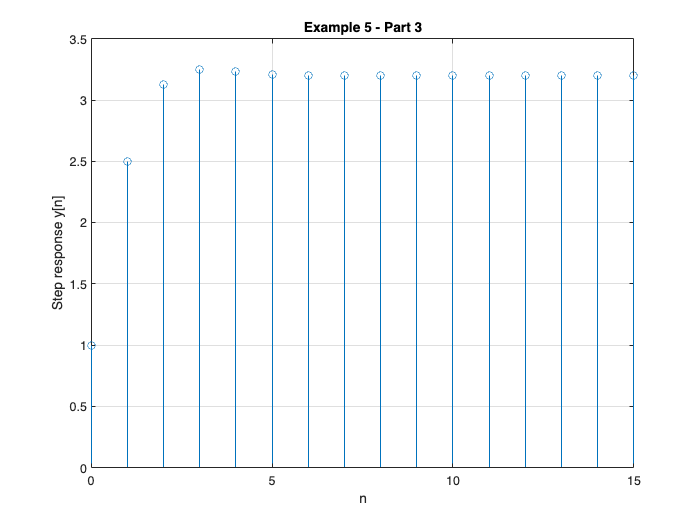

stem([0:15], yn)
grid
title('Example 5 - Part 3')
xlabel('n')
ylabel('Step response y[n]')

## Response as stepwise continuous y(t)

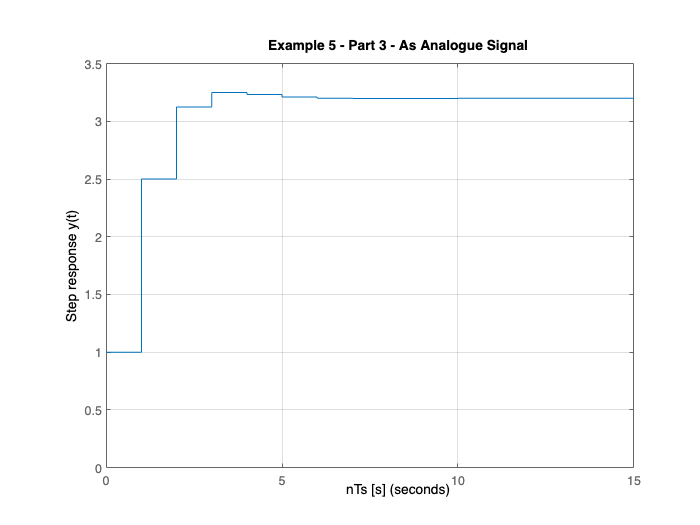

step(Hz,15)
grid
title('Example 5 - Part 3 - As Analogue Signal')
xlabel('nTs [s]')
ylabel('Step response y(t)')
axis([0,15,0,3.5])